clc;
clear all;
close all;
% Read the .wav file
[x, fs] = audioread("Goutami.wav");

% Digital filter specifications
Sampling_frequency = fs

Sampling_frequency = 44100

Transition_band = 900

Transition_band = 900

Fp = 3 * 10^3

Fp = 3000

Ks = 74

Ks = 74

Fs = 3.9 * 10^3

Fs = 3900

Sampling_time = 1 / Sampling_frequency

Sampling_time = 2.2676e-05

Omega_p = 2 * pi * Fp

Omega_p = 1.8850e+04

Omega_s = 2 * pi * (Fp + Transition_band)

Omega_s = 2.4504e+04


% Converting the analog filter specifications into digital specifications
Wp = Omega_p * Sampling_time

Wp = 0.4274

Ws = Omega_s * Sampling_time

Ws = 0.5557


% The filter should provide minimum 74 dB attenuation in the stop band
k = 6 % k value for blackmann

k = 6

N = (8 * pi) / (Ws - Wp);
N = ceil(N)

N = 196

if (mod(N,2)==0)
  Alpha = N / 2
else
  Alpha = (N - 1) / 2
end

% Cutoff frequency
Wc = Wp + ((Ws - Wp) / 2);

% Impulse response of the FIR lowpass filter using the Blackman window

WHam = 0.42 - 0.5 * cos(2 * pi * (0:N-1) / (N-1)) + 0.08 * cos(4 * pi * (0:N-1) / (N-1)); 

h_blackman = ideal_lp_filter(Wc, N) .* WHam;
display(length(x));

      132300



display(length(h_blackman));

   196



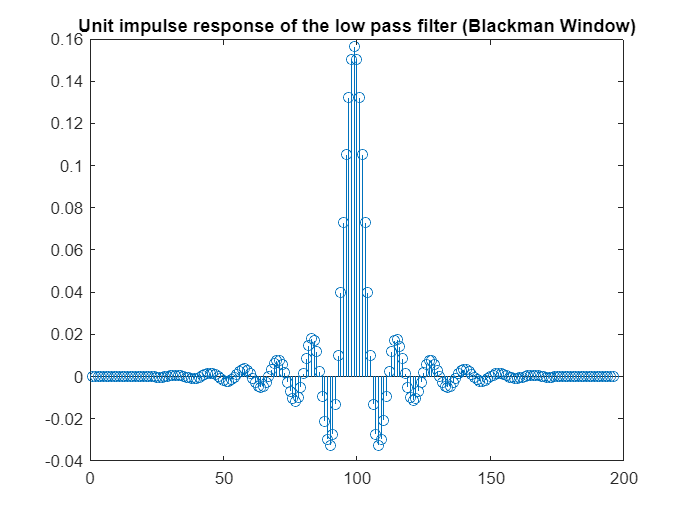

stem(h_blackman);

title('Unit impulse response of the low pass filter (Blackman Window)');

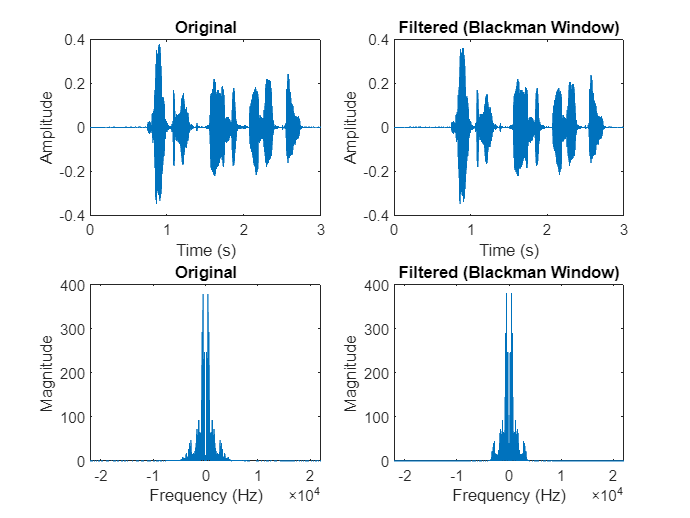

res = conv(x, h_blackman);

subplot(2,2,1);
t = (0:length(x)-1) / fs;
plot(t, x);
title('Original');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(res)-1) / Sampling_frequency; % Time vector

subplot(2,2,2);
plot(t, res);
title('Filtered (Blackman Window)');
xlabel('Time (s)');
ylabel('Amplitude');

n = length(x);  % Set n based on the length of the signal
y = fft(x, n);
m = abs(y);
f = (0:length(y)-1) * fs / length(y);
Y = fftshift(m);
fshift = (-n/2:n/2-1) * (fs/n);

% Filtered
nf = length(res);  % Set n based on the length of the signal
yf = fft(res, nf);
mf = abs(yf);
ff = (0:length(yf)-1) * Sampling_frequency / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (Sampling_frequency/nf);

subplot(2,2,3);
plot(fshift, Y);
title('Original');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered (Blackman Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


% Ideal lowpass filter function


function hd = ideal_lp_filter(Wc, N)
    % Ideal lowpass filter function
    % Wc: Cutoff frequency
    % N: Filter order
    n = 0:N-1;
    hd = Wc / pi * sinc(Wc * (n - (N / 2)) / pi);
end